%calculating the mean first passage time analytically/numerically 
%to investigate effect of multiple invader-substrate mismatches on RNA/DNA
%toehold exchange kinetics including spontaneous incumbent dissociation

b = 20 %define branch migration domain length

b = 20

g = 7 %define invader toehold length

g = 7

g2 = 2 %define incumbent toehold length

g2 = 2


bg2 = b + g2 %define branch migration domain + incumbent toehold length 

bg2 = 22


m = zeros(1, 4)

m =      0     0     0     0


m(1) = 2 %define position of first mismatch

m =      2     0     0     0



R = 1.987/1000 %universal gas constant in kcal/K/mol 

R = 0.0020

temp = 298.15 %temperature in K

temp = 298.1500

%free energy parameters
dGassoc = 2.6*R*temp

dGassoc = 1.5403

dGbp = -2.52*R*temp

dGbp = -1.4929

dGrd = -0.5*R*temp

dGrd = -0.2962

dGp = 3.6*R*temp

dGp = 2.1327

dGmm = 9.5*R*temp

dGmm = 5.6280

dGbm = 7.4*R*temp 

dGbm = 4.3839

%absolute rate constant
k_bp = 5.4*10^7

k_bp = 54000000

k_eff = zeros(4,20)

k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = zeros(4, 20)

first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound = zeros(4, 20)

prob_unbound =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


k_eff_perf = zeros(4, 20)

k_eff_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time_perf = zeros(4, 20)

first_pass_time_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound_perf = zeros(4, 20)

prob_unbound_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%loop through number of mismatches
for ind = 2:5
    %loop through position of mismatches
    for pos = m(ind-1)+1:b
        m(ind) = pos
        
        %define forward and reverse transition rates
        k_AA = 0;
        k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
        k_B1A = k_bp * exp((dGbp + dGrd)/(R*temp))
        k_BC1ij = k_bp;
        k_BC1ji = k_bp * exp((dGbp + dGrd)/(R*temp))
        k_C1f = k_bp * exp(-(dGbm + dGp)/(R*temp))
        k_Cf = k_bp * exp(-dGbm/(R*temp))
        k_Cr = k_bp * exp(-(dGbm - dGrd)/(R*temp))
        k_Crm = k_bp* exp((dGmm - dGbm + dGrd)/(R*temp)) %I have added the + dGrd
        k_Crm_end = k_bp * exp((dGmm - dGbm - dGp + dGrd)/(R*temp)) %I have added the + dGrd
        k_DC = k_bp * exp(-(dGbm + dGp - dGrd)/(R*temp))
        k_DEij = k_bp * exp(dGbp/(R*temp));
        k_DEji = k_bp;
        k_EF = k_bp * exp(dGbp/(R*temp));
        k_FE = 0
        k_FF = 1    
    
        
        if g == 1
            %create arrays of forward and reverse transition rates for
            %mismatch-free system
            Kf_perf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-1]), k_C1f, k_AB1]
            Kb_perf = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_B1A, k_AA]
        
            %create arrays of forward and reverse transition rates for
            %mismatch system
            Kf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-1]), k_C1f, k_AB1]
            Kb = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_B1A, k_AA]
            for no = 1:ind
                if m(no) == b
                    Kb(b + g2 - m(no) + 1) = k_Crm_end
                else
                    Kb(b + g2 - m(no) + 1) = k_Crm
                end
            end
   
            %define spontaneous incumbent dissociation rates
            Koff = [repmat(0, [1, g2+1])];
            for n = g2 + 1:bg2-1
                Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
            end
            Koff = horzcat(Koff, [0, 0])
        
        else
            %create arrays of forward and reverse transition rates for
            %mismatch-free system
            Kf_perf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-1]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
            Kb_perf = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
        
            %create arrays of forward and reverse transition rates for
            %mismatch system
            Kf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-1]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
            Kb = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
            for no = 1:ind
                if m(no) == b
                    Kb(b + g2 - m(no) + 1) = k_Crm_end
                else 
                    Kb(b + g2 - m(no) + 1) = k_Crm
                end
            end
        
            %define spontaneous incumbent dissociation rates
            Koff = [repmat(0, [1, g2+1])]; 
            for n = g2 + 1:bg2-1
                Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
            end
            Koff = horzcat(Koff, [repmat(0, [1, g+1])])
        
        end
        
        Pn_jN_1 = zeros(1,numel(Kf))
        jn_jN_1 = zeros(1,numel(Kf))
        Pn_jN_1 (1) = 0;
        jn_jN_1 (1) = 1;
        
        %calculate flux between each state for mismatch system
        for Pn = 2:numel(Kf)
            Pn_jN_1(Pn)  = 1/Kf(Pn) * jn_jN_1 (Pn-1) + (Kb(Pn-1)/Kf(Pn))*Pn_jN_1(Pn-1);
            jn_jN_1(Pn) = jn_jN_1(Pn-1) + Koff(Pn) * Pn_jN_1(Pn);
        end
        
        Pn_jN_1_perf = zeros(1,numel(Kf_perf))
        jn_jN_1_perf = zeros(1,numel(Kf_perf))
        Pn_jN_1_perf (1) = 0;
        jn_jN_1_perf (1) = 1;
        
        %calculate flux between each state for mismatch-free system
        for Pn = 2:numel(Kf_perf)
            Pn_jN_1_perf(Pn)  = 1/Kf_perf(Pn) * jn_jN_1_perf (Pn-1) + (Kb_perf(Pn-1)/Kf_perf(Pn))*Pn_jN_1_perf(Pn-1);
            jn_jN_1_perf(Pn) = jn_jN_1_perf(Pn-1) + Koff(Pn) * Pn_jN_1_perf(Pn);
        end
    
        first_pass_time (ind - 1, pos) = (1/jn_jN_1(end-1))*sum(Pn_jN_1) %first passage time for mismatch system
        k_eff (ind-1, pos) = 1/(first_pass_time (ind - 1, pos)*(5*10^-8)); %effective rate constant for mismatch system
        prob_unbound(ind-1, pos) = Pn_jN_1(end)/sum(Pn_jN_1) %prob of being in unbound state for mismatch system
    
        first_pass_time_perf (ind-1, pos) = (1/jn_jN_1_perf(end-1))*sum(Pn_jN_1_perf) %first passage time for mismatch-free system
        k_eff_perf (ind - 1, pos) = 1/(first_pass_time_perf (ind-1, pos)*(5*10^-8)); %effective rate constant for mismatch-free system
        prob_unbound_perf(ind-1, pos) = Pn_jN_1_perf(end)/sum(Pn_jN_1_perf) %prob of being in unbound state for mismatch-free system
    end
    m(ind) = m(ind-1) + 3; %introduce space between mismatches
end

m =      2     3     0     0


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf = 	1.0e+07 *

         0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb = 	1.0e+08 *

         0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb = 	1.0e+08 *

         0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff = 	1.0e+04 *

         0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+05 *

         0         0    1.4293         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     4     0     0


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf = 	1.0e+07 *

         0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb = 	1.0e+08 *

         0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb = 	1.0e+08 *

         0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff = 	1.0e+04 *

         0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+05 *

         0         0    1.4293    0.8668         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     0     0


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf = 	1.0e+07 *

         0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb = 	1.0e+08 *

         0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb = 	1.0e+08 *

         0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff = 	1.0e+04 *

         0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    1.4293    0.8668    0.5257         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     6     0     0


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    1.4293    0.8668    0.5257    0.3188         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     7     0     0


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    1.4293    0.8668    0.5257    0.3188    0.1933         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     8     0     0


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    1.4293    0.8668    0.5257    0.3188    0.1933    0.1172         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     9     0     0


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    1.4293    0.8668    0.5257    0.3188    0.1933    0.1172    0.0710         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2    10     0     0


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    1.4293    0.8668    0.5257    0.3188    0.1933    0.1172    0.0710    0.0430         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2    11     0     0


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    1.4293    0.8668    0.5257    0.3188    0.1933    0.1172    0.0710    0.0430    0.0260         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2    12     0     0


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    1.4293    0.8668    0.5257    0.3188    0.1933    0.1172    0.0710    0.0430    0.0260    0.0157         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2    13     0     0


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    1.4293    0.8668    0.5257    0.3188    0.1933    0.1172    0.0710    0.0430    0.0260    0.0157    0.0094         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2    14     0     0


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    1.4293    0.8668    0.5257    0.3188    0.1933    0.1172    0.0710    0.0430    0.0260    0.0157    0.0094    0.0056         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2    15     0     0


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    1.4293    0.8668    0.5257    0.3188    0.1933    0.1172    0.0710    0.0430    0.0260    0.0157    0.0094    0.0056    0.0032         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2    16     0     0


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    1.4293    0.8668    0.5257    0.3188    0.1933    0.1172    0.0710    0.0430    0.0260    0.0157    0.0094    0.0056    0.0032    0.0013         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2    17     0     0


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    1.4293    0.8668    0.5257    0.3188    0.1933    0.1172    0.0710    0.0430    0.0260    0.0157    0.0094    0.0056    0.0032    0.0013    0.0003         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2    18     0     0


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    1.4293    0.8668    0.5257    0.3188    0.1933    0.1172    0.0710    0.0430    0.0260    0.0157    0.0094    0.0056    0.0032    0.0013    0.0003    0.0002         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685    0.3309         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2    19     0     0


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    1.4293    0.8668    0.5257    0.3188    0.1933    0.1172    0.0710    0.0430    0.0260    0.0157    0.0094    0.0056    0.0032    0.0013    0.0003    0.0002    0.0002         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685    0.3309    0.3362         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2    20     0     0


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0731    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    1.4293    0.8668    0.5257    0.3188    0.1933    0.1172    0.0710    0.0430    0.0260    0.0157    0.0094    0.0056    0.0032    0.0013    0.0003    0.0002    0.0002    0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685    0.3309    0.3362    0.3365
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     6     0


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    0.0014    0.0009    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    4.2562         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685    0.3309    0.3362    0.3365
         0         0         0         0         0    0.1393         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0    5.2472         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     7     0


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    0.0014    0.0009    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    4.2562    2.5795         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685    0.3309    0.3362    0.3365
         0         0         0         0         0    0.1393    0.1393         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0    5.2472    5.2472         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8     0


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    0.0014    0.0009    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    4.2562    2.5795    1.5625         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685    0.3309    0.3362    0.3365
         0         0         0         0         0    0.1393    0.1393    0.1393         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0    5.2472    5.2472    5.2472         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     9     0


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    0.0014    0.0009    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    4.2562    2.5795    1.5625    0.9457         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685    0.3309    0.3362    0.3365
         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5    10     0


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    0.0014    0.0009    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    4.2562    2.5795    1.5625    0.9457    0.5716         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685    0.3309    0.3362    0.3365
         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5    11     0


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    0.0014    0.0009    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    4.2562    2.5795    1.5625    0.9457    0.5716    0.3447         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685    0.3309    0.3362    0.3365
         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5    12     0


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    0.0014    0.0009    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    4.2562    2.5795    1.5625    0.9457    0.5716    0.3447    0.2070         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685    0.3309    0.3362    0.3365
         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5    13     0


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    0.0014    0.0009    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    4.2562    2.5795    1.5625    0.9457    0.5716    0.3447    0.2070    0.1235         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685    0.3309    0.3362    0.3365
         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5    14     0


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    0.0014    0.0009    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    4.2562    2.5795    1.5625    0.9457    0.5716    0.3447    0.2070    0.1235    0.0726         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685    0.3309    0.3362    0.3365
         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5    15     0


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    0.0014    0.0009    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    4.2562    2.5795    1.5625    0.9457    0.5716    0.3447    0.2070    0.1235    0.0726    0.0401         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685    0.3309    0.3362    0.3365
         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5    16     0


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    0.0014    0.0009    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    4.2562    2.5795    1.5625    0.9457    0.5716    0.3447    0.2070    0.1235    0.0726    0.0401    0.0148         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685    0.3309    0.3362    0.3365
         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5    17     0


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    0.0014    0.0009    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    4.2562    2.5795    1.5625    0.9457    0.5716    0.3447    0.2070    0.1235    0.0726    0.0401    0.0148    0.0021         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685    0.3309    0.3362    0.3365
         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1394         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5    18     0


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    0.0014    0.0009    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    4.2562    2.5795    1.5625    0.9457    0.5716    0.3447    0.2070    0.1235    0.0726    0.0401    0.0148    0.0021    0.0006         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685    0.3309    0.3362    0.3365
         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1394    0.1394         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5    19     0


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    0.0014    0.0009    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    4.2562    2.5795    1.5625    0.9457    0.5716    0.3447    0.2070    0.1235    0.0726    0.0401    0.0148    0.0021    0.0006    0.0005         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685    0.3309    0.3362    0.3365
         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1394    0.1394    0.1394         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5    20     0


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0731    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    0.0014    0.0009    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    4.2562    2.5795    1.5625    0.9457    0.5716    0.3447    0.2070    0.1235    0.0726    0.0401    0.0148    0.0021    0.0006    0.0005    0.0005
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685    0.3309    0.3362    0.3365
         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1394    0.1394    0.1394    0.1394
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8     9


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0004    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    1.2628         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685    0.3309    0.3362    0.3365
         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1394    0.1394    0.1394    0.1394
         0         0         0         0         0         0         0         0    0.1393         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0         0         0         0    5.2472         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8    10


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0004    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    1.2628    0.7631         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685    0.3309    0.3362    0.3365
         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1394    0.1394    0.1394    0.1394
         0         0         0         0         0         0         0         0    0.1393    0.1393         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0         0         0         0    5.2472    5.2472         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8    11


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0004    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    1.2628    0.7631    0.4599         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685    0.3309    0.3362    0.3365
         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1394    0.1394    0.1394    0.1394
         0         0         0         0         0         0         0         0    0.1393    0.1393    0.1393         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0         0         0         0    5.2472    5.2472    5.2472         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8    12


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0004    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    1.2628    0.7631    0.4599    0.2760         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685    0.3309    0.3362    0.3365
         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1394    0.1394    0.1394    0.1394
         0         0         0         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8    13


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0004    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    1.2628    0.7631    0.4599    0.2760    0.1645         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685    0.3309    0.3362    0.3365
         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1394    0.1394    0.1394    0.1394
         0         0         0         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8    14


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0004    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    1.2628    0.7631    0.4599    0.2760    0.1645    0.0964         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685    0.3309    0.3362    0.3365
         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1394    0.1394    0.1394    0.1394
         0         0         0         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8    15


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0004    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    1.2628    0.7631    0.4599    0.2760    0.1645    0.0964    0.0530         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685    0.3309    0.3362    0.3365
         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1394    0.1394    0.1394    0.1394
         0         0         0         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8    16


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0004    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    1.2628    0.7631    0.4599    0.2760    0.1645    0.0964    0.0530    0.0192         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685    0.3309    0.3362    0.3365
         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1394    0.1394    0.1394    0.1394
         0         0         0         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8    17


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0004    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    1.2628    0.7631    0.4599    0.2760    0.1645    0.0964    0.0530    0.0192    0.0023         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685    0.3309    0.3362    0.3365
         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1394    0.1394    0.1394    0.1394
         0         0         0         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8    18


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0004    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    1.2628    0.7631    0.4599    0.2760    0.1645    0.0964    0.0530    0.0192    0.0023    0.0003         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685    0.3309    0.3362    0.3365
         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1394    0.1394    0.1394    0.1394
         0         0         0         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8    19


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0004    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    1.2628    0.7631    0.4599    0.2760    0.1645    0.0964    0.0530    0.0192    0.0023    0.0003    0.0002         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685    0.3309    0.3362    0.3365
         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1394    0.1394    0.1394    0.1394
         0         0         0         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8    20


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0731    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0004    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    1.2628    0.7631    0.4599    0.2760    0.1645    0.0964    0.0530    0.0192    0.0023    0.0003    0.0002    0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685    0.3309    0.3362    0.3365
         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1394    0.1394    0.1394    0.1394
         0         0         0         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8    11    12


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    0.0013    0.0008    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0         0         0    3.1365         0         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685    0.3309    0.3362    0.3365
         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1394    0.1394    0.1394    0.1394
         0         0         0         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393
         0         0         0         0         0         0         0         0         0         0         0    0.1393         0         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0         0         0         0         0         0         0    5.2472         0         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0         0         0         0    0.9992         0         0         0         0         0         0         0         0


m =      2     5     8    11    13


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    0.0013    0.0008    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0         0         0    3.1365    1.9881         0         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685    0.3309    0.3362    0.3365
         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1394    0.1394    0.1394    0.1394
         0         0         0         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393
         0         0         0         0         0         0         0         0         0         0         0    0.1393    0.1393         0         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0         0         0         0         0         0         0    5.2472    5.2472         0         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0         0         0         0    0.9992    0.9992         0         0         0         0         0         0         0


m =      2     5     8    11    14


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    0.0013    0.0008    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0         0         0    3.1365    1.9881    1.2126         0         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685    0.3309    0.3362    0.3365
         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1394    0.1394    0.1394    0.1394
         0         0         0         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393
         0         0         0         0         0         0         0         0         0         0         0    0.1393    0.1393    0.1393         0         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0         0         0         0         0         0         0    5.2472    5.2472    5.2472         0         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992         0         0         0         0         0         0


m =      2     5     8    11    15


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    0.0013    0.0008    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0         0         0    3.1365    1.9881    1.2126    0.6831         0         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685    0.3309    0.3362    0.3365
         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1394    0.1394    0.1394    0.1394
         0         0         0         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393
         0         0         0         0         0         0         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393         0         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0         0         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472         0         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992         0         0         0         0         0


m =      2     5     8    11    16


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    0.0013    0.0008    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0         0         0    3.1365    1.9881    1.2126    0.6831    0.2514         0         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685    0.3309    0.3362    0.3365
         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1394    0.1394    0.1394    0.1394
         0         0         0         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393
         0         0         0         0         0         0         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393         0         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0         0         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472         0         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0         0


m =      2     5     8    11    17


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    0.0013    0.0008    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0         0         0    3.1365    1.9881    1.2126    0.6831    0.2514    0.0284         0         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685    0.3309    0.3362    0.3365
         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1394    0.1394    0.1394    0.1394
         0         0         0         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393
         0         0         0         0         0         0         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393         0         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0         0         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472         0         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0         0


m =      2     5     8    11    18


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    0.0013    0.0008    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0         0         0    3.1365    1.9881    1.2126    0.6831    0.2514    0.0284    0.0020         0         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685    0.3309    0.3362    0.3365
         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1394    0.1394    0.1394    0.1394
         0         0         0         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393
         0         0         0         0         0         0         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393         0         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0         0         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472         0         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0         0


m =      2     5     8    11    19


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    2.6746    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    0.0013    0.0008    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0         0         0    3.1365    1.9881    1.2126    0.6831    0.2514    0.0284    0.0020    0.0005         0


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685    0.3309    0.3362    0.3365
         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1394    0.1394    0.1394    0.1394
         0         0         0         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393
         0         0         0         0         0         0         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393         0


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0         0         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472         0


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992         0


m =      2     5     8    11    20


k_AB1 = 0.2005

k_B1A = 2.6353e+06

k_BC1ji = 2.6353e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.0020e+04

k_Crm = 2.6746e+08

k_Crm_end = 7.3081e+06

k_DC = 547.0251

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635    0.2635         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0000    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Kb =          0    0.5400    0.0731    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0002    2.6746    0.0002    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264    0.0264         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0    0.0013    0.0008    0.0005    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0         0         0    3.1365    1.9881    1.2126    0.6831    0.2514    0.0284    0.0020    0.0005    0.0005


prob_unbound =          0         0    0.1394    0.1394    0.1394    0.1395    0.1396    0.1397    0.1399    0.1403    0.1410    0.1421    0.1439    0.1470    0.1529    0.1732    0.2685    0.3309    0.3362    0.3365
         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1394    0.1394    0.1394    0.1394
         0         0         0         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393
         0         0         0         0         0         0         0         0         0         0         0    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393    0.1393


first_pass_time_perf =          0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472
         0         0         0         0         0         0         0         0         0         0         0    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472    5.2472


prob_unbound_perf =          0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992
         0         0         0         0         0         0         0         0         0         0         0    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992    0.9992


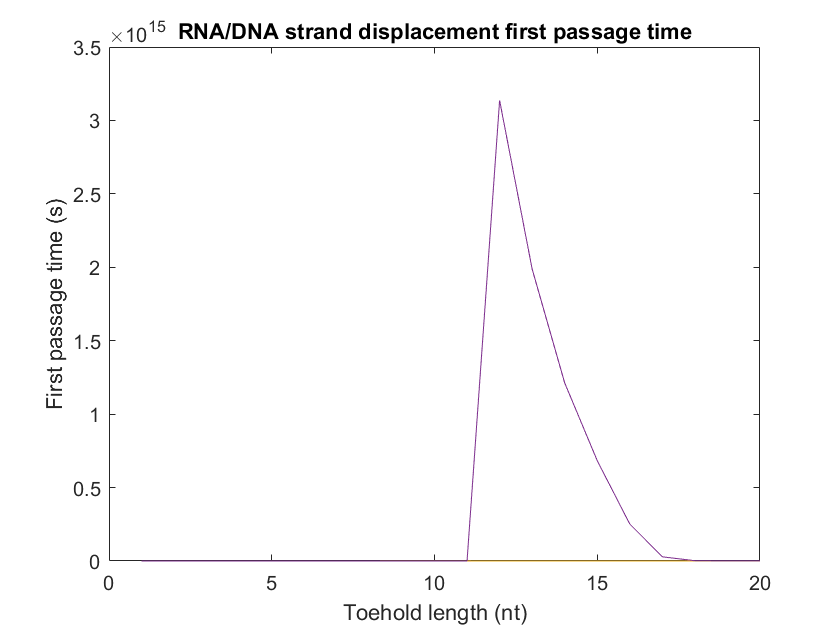

plot(1:20, first_pass_time)
ylabel('First passage time (s)')
xlabel('Toehold length (nt)')
title('RNA/DNA strand displacement first passage time')

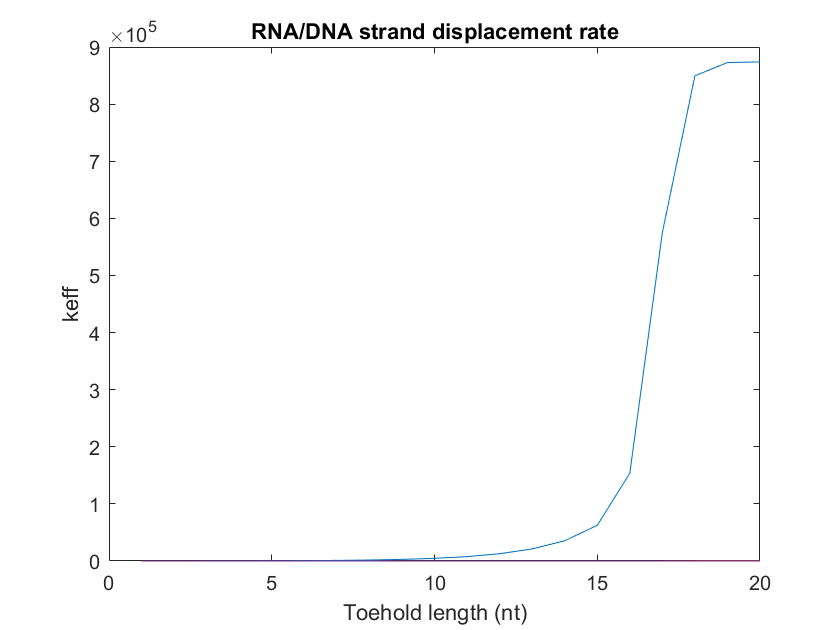


plot(1:20, k_eff)
xlabel('Toehold length (nt)')
ylabel('keff')
title('RNA/DNA strand displacement rate')

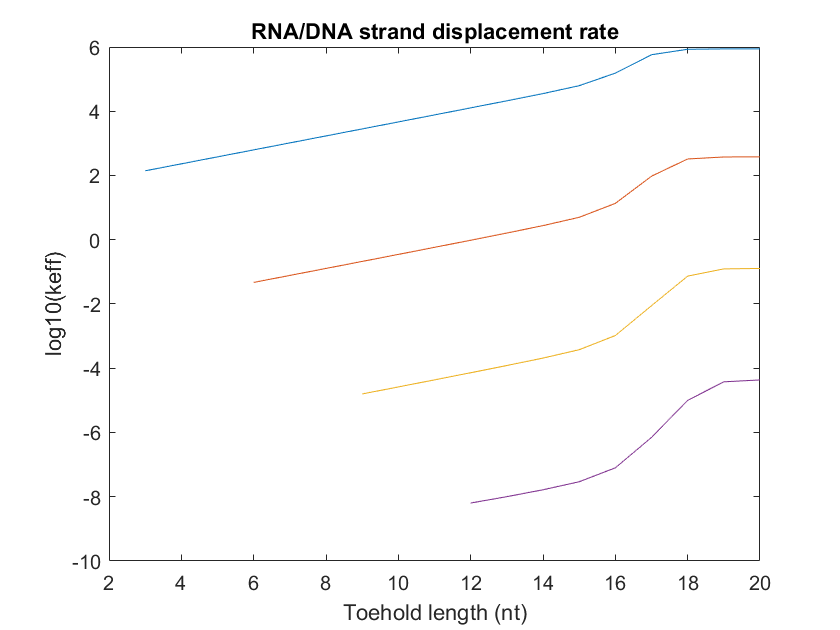


plot(1:20, log10(k_eff))
xlabel('Toehold length (nt)')
ylabel('log10(keff)')
title('RNA/DNA strand displacement rate') 

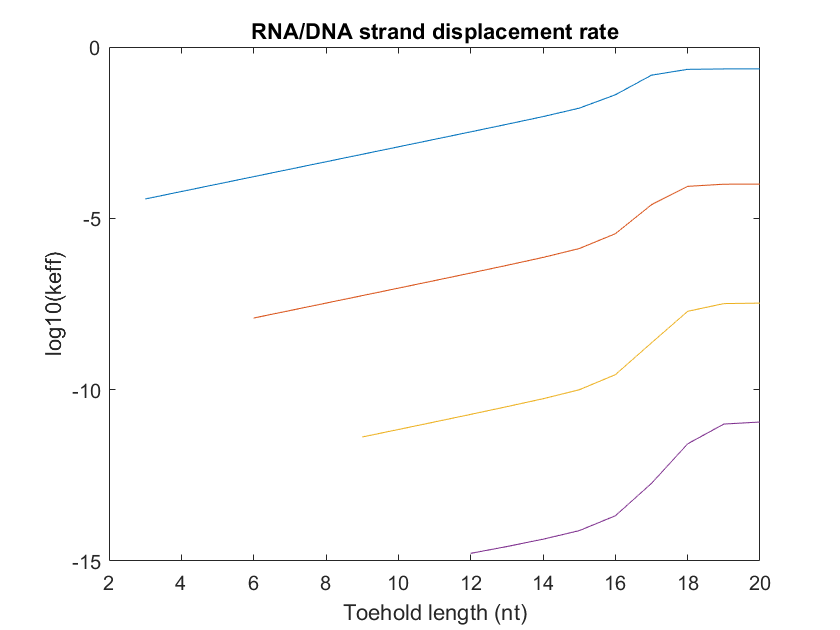


plot(1:20, log10(k_eff./k_eff_perf))
xlabel('Toehold length (nt)')
ylabel('log10(keff)')
title('RNA/DNA strand displacement rate') 